# Moving Furniture in a Cluttered Room with RRT

This example shows how to plan a path to move bulky furniture in a tight space avoiding poles. This example shows a workflow of the "Piano Mover's Problem", which is used for testing path planning algorithms with constrained state spaces. This example uses the `plannerRRTStar` object to implement a custom optimized rapidly-exploring tree (RRT*) algoirthm. Provided example helpers illustrate how to define custom state spaces and state valdiation for any motion planning application.

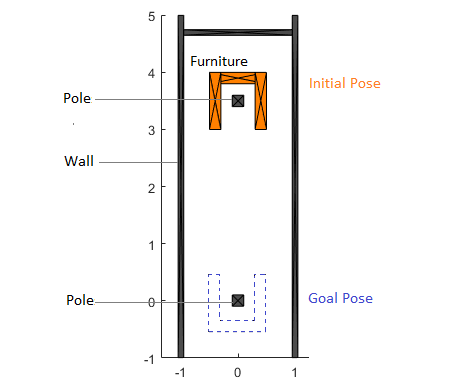

## Model the Scene

To help visualize and solve this path planning problem, two helper classes are provided, `ExampleHelperFurniture` and `ExampleHelperRoom`. The `ExampleHelperFurniture` class assembles the furniture by putting three rectangle collision boxes together. The furniture is set up as below:

The `ExampleHelperRoom` defines the dimension of the room and provides functions to insert furniture into the room and to check whether the furniture is in collision with the walls or poles. These two classes are used for the state validator of the planner.

Show the room with a given length and width. Add a piece of furniture with a given pose.

len = 6;
wid = 2;
room = ExampleHelperRoom(len, wid);
chair = ExampleHelperFurniture;
addFurniture(room,chair,trvec2tform([0 3.5 0]));
show(room,gca)
axis equal

## Configure State Space

Create a `stateSpaceSE2` object for the furniture. Set the bounds based on the room dimensions. The state space samples random states in the state space. In this example, the furniture state is a 3-element vector, `[x y theta]`, for the *xy*-coordinates and angle of rotation in radians.

bounds = [-0.8 0.8; [-1 5]; [-pi pi]];

ss = stateSpaceSE2(bounds);
ss.WeightTheta = 2;

## Create a Custom State Validator

The planner requires a customized state validator to enable collision checking between furniture and the fixtures in the room. The provided class, `ExampleHelperFurnitureInRoomValidator`, checks the validity of the furniture states based on the pairwise convex polygon collision checking functions. The class automatically creates a room and puts the weird-shaped furniture in it at construction.

% Set the initial pose of the furniture
initPose = trvec2tform([0 3.5 0]);

% Create a customized state validator
sv = ExampleHelperFurnitureInRoomValidator(ss, initPose);

% Reduce the validation distance
% Validation distance determines the granularity of interpolation when
% checking the motion that connects two states.
sv.ValidationDistance = 0.1;

## Configure the Path Planner

Use `plannerRRTStar` as the planner and specify the custom state space and state validator. Specify additional parameters for the planner. The `GoalReached` example helper function returns `true` when a feasible path gets close enough to the goal within a threshold. This exits the planner.

% Create the planner
rrt = plannerRRTStar(ss, sv);

% Set ball radius for searching near neighbors
rrt.BallRadiusConstant = 1000;

% Exit as soon as a path is found
rrt.ContinueAfterGoalReached = false;

% The motion length between two furniture poses should be less than 0.4 m
rrt.MaxConnectionDistance = 0.4;

% Increase the max iterations
rrt.MaxIterations = 20000;

% Use a customized goal function 
rrt.GoalReachedFcn = @exampleHelperGoalFunc;

## Plan the Move

Set a start and end pose for the furniture. This example moves from one pole to the other and rotates the chair `pi` radians. Plan the path between poses. Visualize the search tree and final path.

% Set the init and goal poses
start = [0 3.5 0];
goal = [0 -0.2 pi];

% Set random number seed for repeatability
rng(0, 'twister');
[path, solnInfo] = plan(rrt,start,goal);

hold on
% Search tree
plot(solnInfo.TreeData(:,1), solnInfo.TreeData(:,2), '.-');
% Interpolate path and plot points
interpolate(path,300)
plot(path.States(:,1), path.States(:,2), 'r-', 'LineWidth', 2)

hold off

## Visualize the Motion

An example helper is provided for smoothing the path by cutting corners of the path where possible. Animate the motion of the furniture from start to goal pose. The animation plot shows intermediate states as the furniture navigates to the goal position.

f = figure;

% Smooth the path, cut the corners wherever possible
pathSm = exampleHelperSmoothPath(path, sv);

interpolate(pathSm,100);
animateFurnitureMotion(sv.Room,1,pathSm.States, axes(f))

% show the trace of furniture
skip = 6;
states = pathSm.States([1:skip:end, pathSm.NumStates], :);
exampleHelperShowFurnitureTrace(sv.Room.FurnituresInRoom{1}, states);

*Copyright 2019 The MathWorks, Inc.*